# TP 6 - Détecteur de visage

## II. Extraction des "Caractéristiques de Haar"

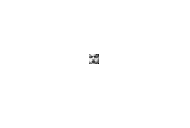

img=imread('training\img1.bmp');
imshow(img)

block44=ones(2,2);
V=haarfeature(img);
[osef,nbfeature]=size(V);
chemin_fic="training\";

dsp1 = ['Nombre de feature: ',num2str(nbfeature)];
disp(dsp1)

Nombre de feature: 3300


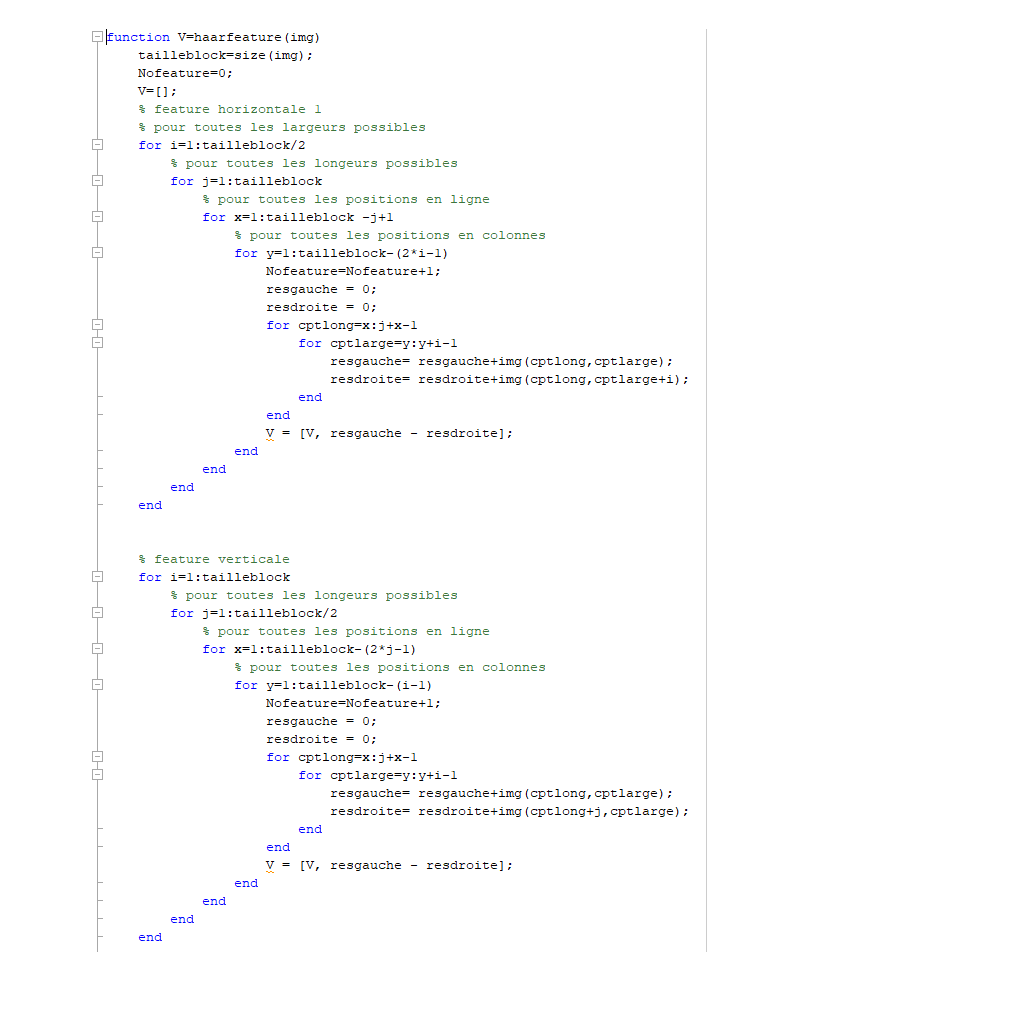

d = dir(strcat(chemin_fic,'*.bmp'));
nbimg=length(find([d.isdir]==0));
groundtruth=[];
T=[];
path='training\img';
for i=1:nbimg  
     file=strcat(path,num2str(i));
     clear img;
     img=imread(file,'bmp');
     V=haarfeature(img);
     T=[T;V];
     if (i<500)
       groundtruth=[groundtruth;1];
     else
       groundtruth=[groundtruth;0];
     end
end
T_gr=[T groundtruth];

figure();
img=imread('code1.png');
imshow(img)

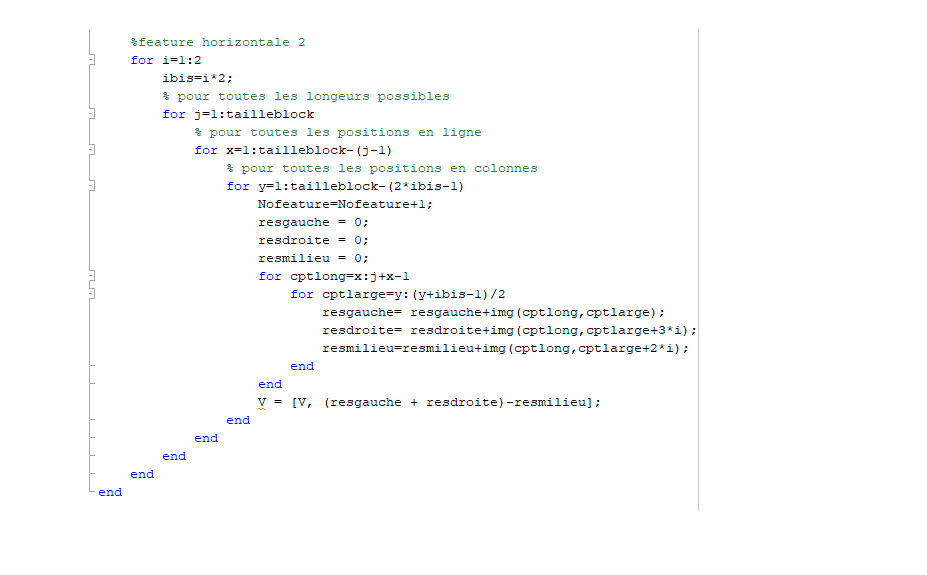

figure();
img=imread('code2.png');
imshow(img)

## III. Decision

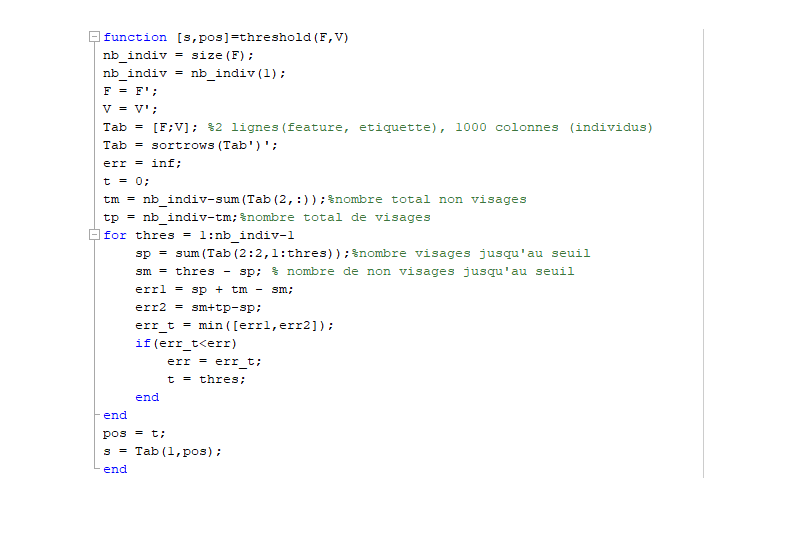

figure();
img=imread('code3.png');
imshow(img)

[s,pos] = threshold(T_gr(:,1),T_gr(:,end))

s = uint8
0

pos = 283